# Outer VRFT - Why does it work so well ?

Here we will just consider the outer loop and collapse the inner loop onto itself using the original controller. The objective is to see if the VRFT actually works anywhere of if the inner loop not working is just a weid fluke.

In this case the plant model is compl. sensitivity of the inner loop multiplied by the integrator.

## Inner Loop Model

PitchRateModel = tf(.4323,  [1, 1.334]) * 66.6667;
R1 = pid(.3, .3, .05, .01);

iloop = loopsens(PitchRateModel, R1);

## Outer Loop

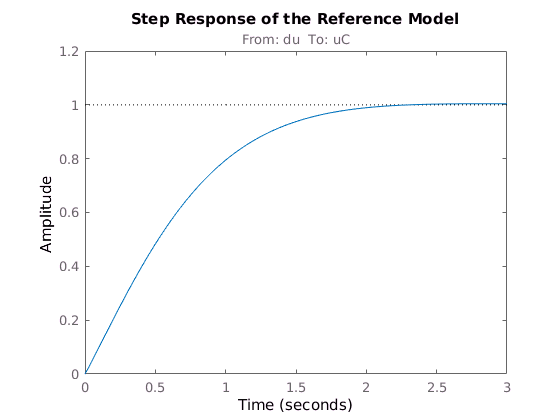

integrator = tf(1, [1, 0]);
R2 = pid(1.61, 0, .00512, .01); 

oloop = loopsens(iloop.Ti * integrator, R2);
ReferenceModel = oloop.Ti;

figure;
    step(ReferenceModel);
    title('Step Response of the Reference Model');


PlantModel = iloop.Ti * integrator;

At a glance the step response is correct. Next we discretise our models for later.

Ts = .01;

PlantModel_dt = c2d(tf(PlantModel), Ts);
ReferenceModel_dt = c2d(tf(ReferenceModel), Ts);

## VRFT Time

First we build the data. For this we can use a wgn sequence. 

% I/O Signals
N = 2000;
time = [0:(N-1)] * Ts;

u = wgn(N, 1, 0);
y = lsim(PlantModel_dt, u, time);

 The outer controller is a PD. The controller class is thus: 

Tf = .1;
ControllerClass = [ 1, tf([1 0], [Tf 1]) ].';
ControllerClass_dt = c2d(ControllerClass, Ts);

And run the VRFT engine.

[OptimalController , Theta] = VRFT1_ry_theta(...
    u, y, ReferenceModel_dt,  ControllerClass_dt, [], [], []);

fprintf('The optimal PID parametters for the inner controller are: \n');

The optimal PID parametters for the inner controller are: 


fprintf('Kp = %+7g, Original: %-7g\n', Theta(1), R2.Kp);

Kp = +1.59011, Original: 1.61   


fprintf('Kd = %+7g, Original: %-7g\n', Theta(2), R2.Kd);  

Kd = +0.00879149, Original: 0.00512


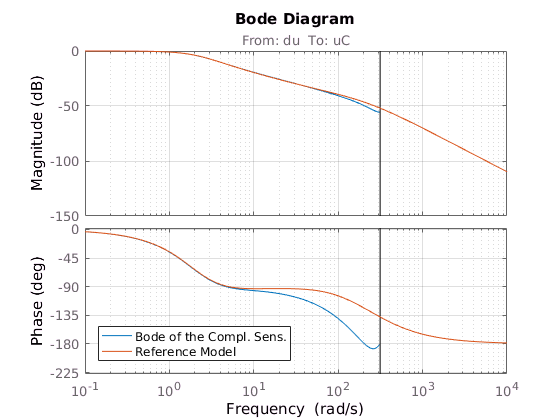


cloop = loopsens(PlantModel_dt, OptimalController); 

figure()
    bode(cloop.Ti, ReferenceModel);
    legend('Bode of the Compl. Sens.', 'Reference Model', 'location', 'SouthWest');
    grid on;

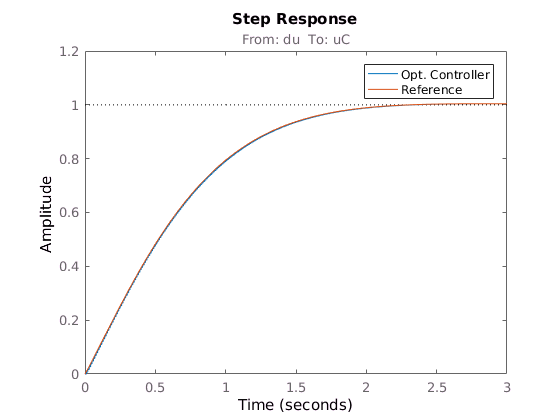

    
figure()
    step(cloop.Ti, ReferenceModel);
    legend('Opt. Controller', 'Reference')